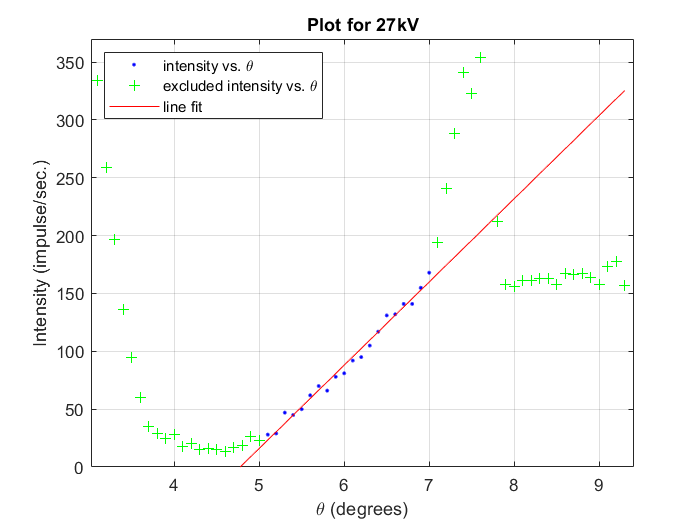

[xData, yData] = prepareCurveData( theta27kV, Rateat27kV );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'Rateat27kV vs. theta27kV', 'Excluded Rateat27kV vs. theta27kV', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel theta27kV
ylabel Rateat27kV
grid on


xlim([3.02 9.41])
ylim([0 370])
legend({'intensity vs. \theta','excluded intensity vs. \theta','line fit'},'Location','northwest')
title('Plot for 27kV')
xlabel('\theta (degrees)')
ylabel('Intensity (impulse/sec.)')


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =       71.95  (67.72, 76.18)    \pm 2.12
 %      p2 =      -343.6  (-369.3, -317.9)  \pm 12.8

%Goodness of fit:
 % SSE: 485.3
 % R-square: 0.9861
 % Adjusted R-square: 0.9853
 % RMSE: 5.193
 
 % \theta_min= 4.776 \pm 0.227